# SIS TD8 calculs symboliques

clearvars
syms z w n


 $S(z)$ zéros et pôles 

% Le 1er filtre
Num1(z)=(1-0*z^(-1))*(1-0*z^(-1))

$$Num1(z) = 1$$

Den1(z)=(1-0.5*z^(-1))*(1-0.2*z^(-1))

$$Den1(z) = \left(\frac{1}{2\,z}-1\right)\,\left(\frac{1}{5\,z}-1\right)$$

S1(z)=Num1/Den1(z);
S1=simplify(S1)

$$S1(z) = \frac{10\,z^{2}}{10\,z^{2}-7\,z+1}$$

% Le 2ème filtre
S2(z)= (10-7*z^(-1)+1*z^(-2))

$$S2(z) = \frac{1}{z^{2}}-\frac{7}{z}+10$$

eqn2=S2(z)==0

$$eqn2 = \frac{1}{z^{2}}-\frac{7}{z}+10=0$$

zero2 = solve(eqn2,z)

$$zero2 = \left(\begin{array}{c} \frac{1}{5}\\ \frac{1}{2} \end{array}\right)$$

% Le produit des deux
S12(z)=S1(z)*S2(z)

$$S12(z) = \frac{10\,z^{2}\,\left(\frac{1}{z^{2}}-\frac{7}{z}+10\right)}{10\,z^{2}-7\,z+1}$$

S12=simplify(S12)

$$S12(z) = 10$$

Calcul du module de  $S(e^{j\omega})$

% Les modules des réponses en fréquence 
assume(w,'real')
H1=subs(S1,z,exp(j*w))

$$H1(z) = \frac{10\,{\mathrm{e}}^{2\,w\,\mathrm{i}}}{1+10\,{\mathrm{e}}^{2\,w\,\mathrm{i}}-7\,{\mathrm{e}}^{w\,\mathrm{i}}}$$

H1=simplify(H1)

$$H1(z) = \frac{10\,{\mathrm{e}}^{2\,w\,\mathrm{i}}}{1+10\,{\mathrm{e}}^{2\,w\,\mathrm{i}}-7\,{\mathrm{e}}^{w\,\mathrm{i}}}$$

modH1=sqrt(real(H1)^2+imag(H1)^2)

$$modH1(z) = \begin{array}{l} 10\,\sqrt{\frac{{\left(\frac{10\,\cos\left(2\,w\right)\,\sigma_{2}}{\sigma_{1}}+\frac{10\,\sin\left(2\,w\right)\,\sigma_{3}}{\sigma_{1}}\right)}^{2}}{100}+\frac{{\left(\frac{10\,\sin\left(2\,w\right)\,\sigma_{2}}{\sigma_{1}}-\frac{10\,\cos\left(2\,w\right)\,\sigma_{3}}{\sigma_{1}}\right)}^{2}}{100}}\\ \mathrm{where}\\ \sigma_{1}={\sigma_{2}}^{2}+{\sigma_{3}}^{2}\\ \sigma_{2}=10\,\cos\left(2\,w\right)-7\,\cos\left(w\right)+1\\ \sigma_{3}=10\,\sin\left(2\,w\right)-7\,\sin\left(w\right) \end{array}$$

simplify(modH1)

$$ans(z) = \frac{5\,\sqrt{2}}{\sqrt{20\,{\cos\left(w\right)}^{2}-77\,\cos\left(w\right)+65}}$$

H2=subs(S2,z,exp(j*w))

$$H2(z) = 10+{\mathrm{e}}^{-2\,w\,\mathrm{i}}-7\,{\mathrm{e}}^{-w\,\mathrm{i}}$$

H2=simplify(H2)

$$H2(z) = 10+{\mathrm{e}}^{-2\,w\,\mathrm{i}}-7\,{\mathrm{e}}^{-w\,\mathrm{i}}$$

modH2=sqrt(real(H2)^2+imag(H2)^2)

$$modH2(z) = \sqrt{{\left(\cos\left(2\,w\right)-7\,\cos\left(w\right)+10\right)}^{2}+{\left(\sin\left(2\,w\right)-7\,\sin\left(w\right)\right)}^{2}}$$

simplify(modH2)

$$ans(z) = \sqrt{40\,{\cos\left(w\right)}^{2}-154\,\cos\left(w\right)+130}$$

fplot(modH1(w),[0 1*pi],'r'); hold on
fplot(modH2(w),[0 1*pi],'b');
fplot(modH2(w)*modH1(w),[0 1*pi],'g');

Réponses impulsionnelles  h1, h2 et h12

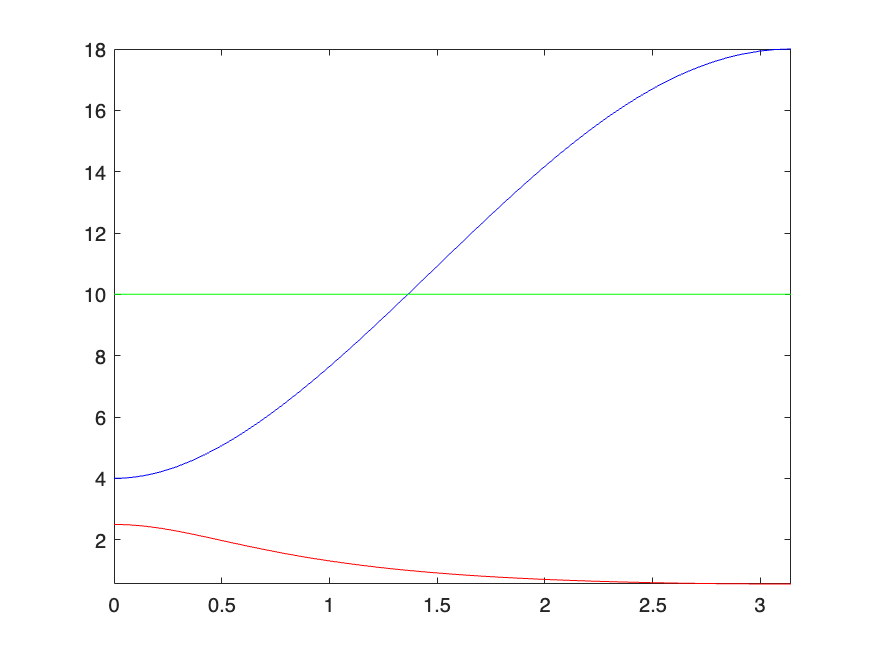

$$h1 = \frac{5\,{\left(\frac{1}{2}\right)}^{n}}{3}-\frac{2\,{\left(\frac{1}{5}\right)}^{n}}{3}$$

h1=iztrans(S1)

h2=iztrans(S2)

$$h2 = \delta_{n-2,0}-7\,\delta_{n-1,0}+10\,\delta_{n,0}$$

h12=iztrans(S12)

$$h12 = 10\,\delta_{n,0}$$

$$h12bis = 10\,0^{n}$$

$$H1bis = \left(\begin{array}{ccc} \frac{10\,z}{z-1} & -\frac{7\,z}{z-1} & \frac{z}{z-1} \end{array}\right)$$

$$H1bis = \left(\begin{array}{ccc} \frac{10\,z}{z-1} & -\frac{7\,z}{z-1} & \frac{z}{z-1} \end{array}\right)$$

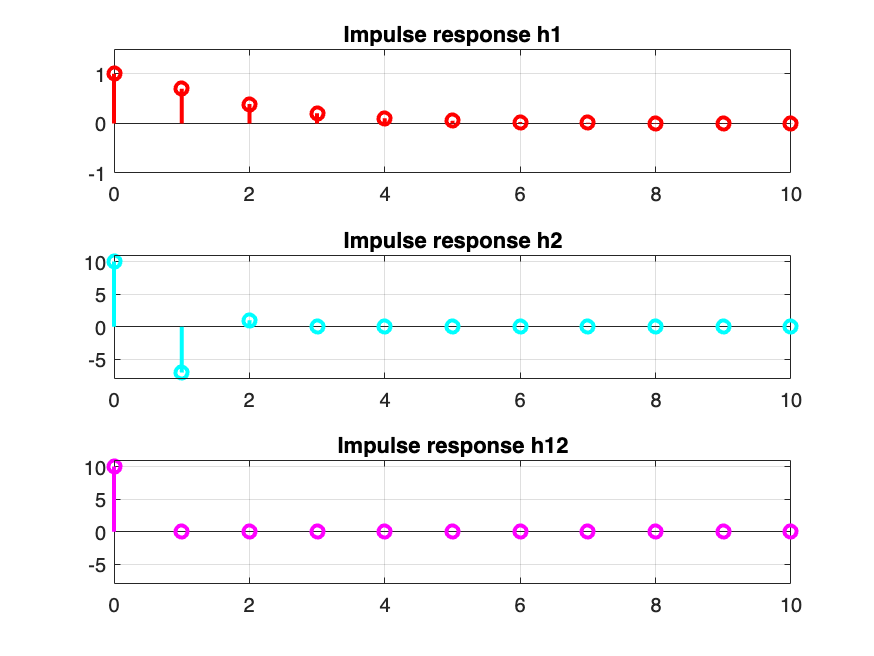


% Methode pour discrétiser le fplot...
m = -0:10;
imp_h1 = double(subs(h1,n,m));
imp_h2 = double(subs(h2,n,m));
imp_h12 = double(subs(h12,n,m));
tiledlayout(3,1)
nexttile;stem(m,imp_h1,'r','lineWidth',2)
ylim([-1 1.5]),grid on;
title('Impulse response h1');
nexttile;stem(m,imp_h2,'c','lineWidth',2)
title('Impulse response h2');
ylim([-8 11]),grid on;
nexttile;stem(m,imp_h12,'m','lineWidth',2)
title('Impulse response h12');
ylim([-8 11]),grid on;